# k-Means algorithm example

Introduce the data

X1 = [2,10];
X2 = [2,5];
X3 = [8,4];
X4 = [5,8];
X5 = [7,5];
X6 = [6,4];
X7 = [1,2];
X8 = [4,9];

D = [X1;X2;X3;X4;X5;X6;X7;X8];
Y = [X5; X6; X8];

Compute the distance between all points

dist = zeros(3);

for j=1:3
    for i=1:8
        dist(i,j)=distance(D(i,:),Y(j,:),2);
    end
end

Select, for each point, the point that minimizes the distance

[v, idx] = min(dist, [], 2);
D = [D,idx];

Plot the clusters:

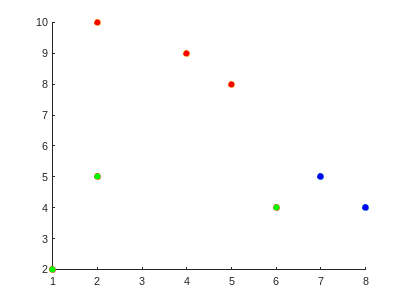

c1 = D(:,3) == 1;
c2 = D(:,3) == 2;
c3 = D(:,3) == 3;
scatter(D(c1,1),D(c1,2), 'MarkerFaceColor', 'b');
hold on
scatter(D(c2,1),D(c2,2), 'MarkerFaceColor', 'g');
scatter(D(c3,1),D(c3,2), 'MarkerFaceColor', 'r');
hold off

Compute the new `Y:`

for i=1:3
    ci = D(:,3) == i;
    x = mean(D(ci,1));
    y = mean(D(ci,2));
    Y(i,:)=[x,y];
end
Y

Y =     7.5000    4.5000
    3.0000    3.6667
    3.6667    9.0000


Repeat the process:

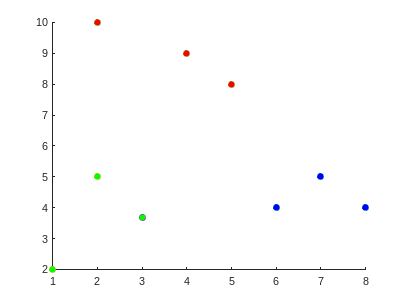

%Distances
for j=1:3
    for i=1:8
        dist(i,j)=distance(D(i,1:2),Y(j,:),2);
    end
end
%Assign
[v, idx] = min(dist, [], 2);
D(:,3) = idx;
%Plot
c1 = D(:,3) == 1;
c2 = D(:,3) == 2;
c3 = D(:,3) == 3;
scatter(D(c1,1),D(c1,2), 'MarkerFaceColor', 'b');
hold on
scatter(Y(1,1),Y(1,2), 'MarkerFaceColor', 'b');
scatter(D(c2,1),D(c2,2), 'MarkerFaceColor', 'g');
scatter(Y(2,1),Y(2,2), 'MarkerFaceColor', 'g');
scatter(D(c3,1),D(c3,2), 'MarkerFaceColor', 'r');
scatter(Y(3,1),Y(3,2), 'MarkerFaceColor', 'r');
hold off

%Optimize
for i=1:3
    ci = D(:,3) == i;
    x = mean(D(ci,1));
    y = mean(D(ci,2));
    Y(i,:)=[x,y];
end
Y

Y =     7.0000    4.3333
    1.5000    3.5000
    3.6667    9.0000


Again:

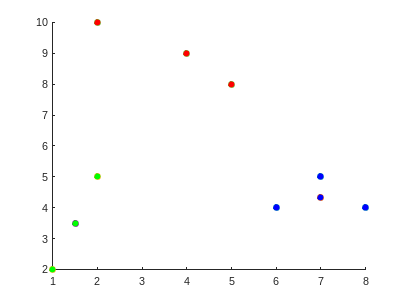

%Distances
for j=1:3
    for i=1:8
        dist(i,j)=distance(D(i,1:2),Y(j,:),2);
    end
end
%Assign
[v, idx] = min(dist, [], 2);
D(:,3) = idx;
%Plot
c1 = D(:,3) == 1;
c2 = D(:,3) == 2;
c3 = D(:,3) == 3;
scatter(D(c1,1),D(c1,2), 'MarkerFaceColor', 'b');
hold on
scatter(Y(1,1),Y(1,2), 'MarkerFaceColor', 'b');
scatter(D(c2,1),D(c2,2), 'MarkerFaceColor', 'g');
scatter(Y(2,1),Y(2,2), 'MarkerFaceColor', 'g');
scatter(D(c3,1),D(c3,2), 'MarkerFaceColor', 'r');
scatter(Y(3,1),Y(3,2), 'MarkerFaceColor', 'r');
hold off

%Optimize
for i=1:3
    ci = D(:,3) == i;
    x = mean(D(ci,1));
    y = mean(D(ci,2));
    Y(i,:)=[x,y];
end
Y

Y =     7.0000    4.3333
    1.5000    3.5000
    3.6667    9.0000


At this point we see how the clusters are the ones that we see naturally with our eyes. If we execute it again, we can see that the changes are very slight now:

%Distances
for j=1:3
    for i=1:8
        dist(i,j)=distance(D(i,1:2),Y(j,:),2);
    end
end
%Assign
[v, idx] = min(dist, [], 2);
D(:,3) = idx;
%Plot
c1 = D(:,3) == 1;
c2 = D(:,3) == 2;
c3 = D(:,3) == 3;
scatter(D(c1,1),D(c1,2), 'MarkerFaceColor', 'b');
hold on
scatter(Y(1,1),Y(1,2), 'MarkerFaceColor', 'b');
scatter(D(c2,1),D(c2,2), 'MarkerFaceColor', 'g');
scatter(Y(2,1),Y(2,2), 'MarkerFaceColor', 'g');
scatter(D(c3,1),D(c3,2), 'MarkerFaceColor', 'r');
scatter(Y(3,1),Y(3,2), 'MarkerFaceColor', 'r');
hold off

%Optimize
for i=1:3
    ci = D(:,3) == i;
    x = mean(D(ci,1));
    y = mean(D(ci,2));
    Y(i,:)=[x,y];
end
Y

Y =     7.0000    4.3333
    1.5000    3.5000
    3.6667    9.0000


In fact, Y is not changing anymore!

#### Functions

function d = distance(X, Y, m)
    n = length(X);
    d = 0;
    for i=1:n
        d = d + (X(i)-Y(i))^m;
    end
    d = sqrt(d);
end
